% Q1: 
% Specify K, mu and covm:
K = 100;
% mu has D values, one per dimension
mu = [400, 500, 600];
covm = [10 2 1;
        2 5 3;
        1 3 8];

% Generate random Gaussian data
rgdata = genGauss(K,mu,covm);

% Q2: Testing and Verification
% The sample mean should be close to 'mu'
sample_mean = mean(rgdata);

% The sample covariance should be close to 'covm'
sample_cov = cov(rgdata);

% Display results to the command window
disp('--- Target Mean ---'); disp(mu);

--- Target Mean ---
   400   500   600



disp('--- Sample Mean ---'); disp(sample_mean);

--- Sample Mean ---
  399.8496  500.2675  599.8470



disp('--- Target Covariance ---'); disp(covm);

--- Target Covariance ---
    10     2     1
     2     5     3
     1     3     8



disp('--- Sample Covariance ---'); disp(sample_cov);

--- Sample Covariance ---
   10.5489    2.7704    1.5302
    2.7704    4.1673    2.6623
    1.5302    2.6623    6.9319



Q3: The function randn() produces K data points using a random sample from a Gaussian distribution. Since it's a sample, it will contain sampling error from the true distribution. Because of this, the sample mean will not be exactly 0 and the sample covariance will not be exactly the identity matrix. This error will persist through the whitening transformation, resulting in a covariance matrix that doesn't exactly match our specified covm.

Q4: In order to ensure the sampling error is removed, we can apply the whitening transform to the sample data itself. We adjust the sample mean to 0 and the sample's covariance matrix to the identity matrix first (via the whitening transformation), then we apply the inverse whitening from Q1 above to get data with our prescribed mean and covariance.

% Get a whitened sample
dims = length(mu); % Set dimensions based on the mean vector
X_w = whitenData(K, dims); % Get a whitened sample

% Verify that the mean of the whitened data is zero
whitened_mean = mean(X_w);
% Verify that the covariance of the whitened data is the identity matrix
whitened_cov = cov(X_w);

% Set the desired mean and covariance for class A, B and C
mu_a = [0, 4, 7];
mu_b = [10, 5, 5];
mu_c = [-2, -5, -5];

covm_a = [6.5 2.1651 1.25;
    2.1651 5.125 2.3816;
    1.25 2.3816 2.375];
covm_b = [3.0184 0.4331 -1.4481;
    0.4331 0.9436 -0.6456;
    -1.4481 -0.6456 1.288];
covm_c = [6.8928 -1.375 3.1945;
    -1.375 3.3572 0.6945;
    3.1945 0.6945 3.75];

% Inverse whiten to get 1000 data points with the above mean/covariance
K = 1000;
X_a = genExactGauss(K,mu_a,covm_a);
X_b = genExactGauss(K,mu_b,covm_b);
X_c = genExactGauss(K,mu_c,covm_c);

% Verify means
disp('--- Mean Class A ---'); disp(mean(X_a));

--- Mean Class A ---
    0.0000    4.0000    7.0000



disp('--- Mean Class B ---'); disp(mean(X_b));

--- Mean Class B ---
   10.0000    5.0000    5.0000



disp('--- Mean Class C ---'); disp(mean(X_c));

--- Mean Class C ---
   -2.0000   -5.0000   -5.0000



% Verify covariance matrices
disp('--- Covariance Class A ---'); disp(cov(X_a));

--- Covariance Class A ---
    6.5000    2.1651    1.2500
    2.1651    5.1250    2.3816
    1.2500    2.3816    2.3750



disp('--- Covariance Class B ---'); disp(cov(X_b));

--- Covariance Class B ---
    3.0184    0.4331   -1.4481
    0.4331    0.9436   -0.6456
   -1.4481   -0.6456    1.2880



disp('--- Covariance Class C ---'); disp(cov(X_c));

--- Covariance Class C ---
    6.8928   -1.3750    3.1945
   -1.3750    3.3572    0.6945
    3.1945    0.6945    3.7500



Q5: We compare our handmade functions with MATLAB's mvnrnd function.

Xalt_a = mvnrnd(mu_a, covm_a, K);
Xalt_b = mvnrnd(mu_b, covm_b, K);
Xalt_c = mvnrnd(mu_c, covm_c, K);

% Print means
disp('--- Mean Class A with mvnrnd ---'); disp(mean(Xalt_a));

--- Mean Class A with mvnrnd ---
    0.0923    3.8868    6.9413



disp('--- Mean Class B with mvnrnd ---'); disp(mean(Xalt_b));

--- Mean Class B with mvnrnd ---
    9.9547    4.9972    5.0188



disp('--- Mean Class C with mvnrnd ---'); disp(mean(Xalt_c));

--- Mean Class C with mvnrnd ---
   -1.9910   -4.9417   -5.0586



% Print covariance matrices
disp('--- Covariance Class A with mvnrnd ---'); disp(cov(Xalt_a));

--- Covariance Class A with mvnrnd ---
    6.7254    2.4555    1.3839
    2.4555    5.5729    2.5479
    1.3839    2.5479    2.3602



disp('--- Covariance Class B with mvnrnd ---'); disp(cov(Xalt_b));

--- Covariance Class B with mvnrnd ---
    3.1248    0.5215   -1.5129
    0.5215    0.9067   -0.6233
   -1.5129   -0.6233    1.2721



disp('--- Covariance Class C with mvnrnd ---'); disp(cov(Xalt_c));

--- Covariance Class C with mvnrnd ---
    6.9778   -1.2304    3.3275
   -1.2304    3.3871    0.7907
    3.3275    0.7907    3.9569



The above means and covariances generated using mvnrnd are close but not exactly equal to the means and covariance matrices we prescribed. This is because, as we found in Q1 to Q3 above, mvnrnd is taking a random sample from the Gaussian distribution we prescribe, but is leaving the sample error in place. In Q4, we applied the whitening transformation to remove the sample error, giving us a sample with exactly the same mean and covariance as the original distribution; it's important to realize that mvnrnd doesn't do this!

Bayesian Optimal decision boundaries are based on the true underlying distribution. Therefore, when visualizing such a decision boundary, we can't use noisy data with sampling error; instead, we need to pre-whiten the data so that the sample mean and covariance match the true mean and covariance.

% Functions

% Q1: A function  to create K samples of D-dimensional Gaussian data
% with specified mean, mu and covariance matrix, covm
function X_m = genGauss(K,mu,covm)
    % Get length of mu
    lenMu = length(mu);
    % Get K random lenMu-dimensional data points (perfect sphere)
    data =  randn(K,lenMu);
    % get the eigendecomposition of covm
    [V, D] = eig(covm);
    % Stretch (D) and rotate (V) the data so it has covariance, covm, then
    % shift it to match the mean, mu -> K x 3
    X_m = (data * sqrt(D) * V') + mu(:)'; % mu must be a row vector
end

% Q4: A function that applies the whitening transformation to a sample of K
% data points randomly drawn from a Gaussian (0,1) distribution.
function X_w = whitenData(K, dims)
    % Generate a random sample from a Gaussian (0,1)
    data = randn(K, dims);
    % Center the data
    data = data - mean(data);
    % Get the eigendecomposition of the covariance matrix
    [V, D] = eig(cov(data));
    % Apply the whitening transformation
    X_w = data * V * inv(sqrt(D));
end

% Q4: We update our function from Q1 so that it uses pre-whitened data
% to perfectly match the mean/covariance
function X_m = genExactGauss(K,mu,covm)
    % Get length of mu
    lenMu = length(mu);
    % Get a whitened sample
    data = whitenData(K, lenMu);
    % get the eigendecomposition of covm
    [V, D] = eig(covm);
    % Stretch (D) and rotate (V) the data so it has covariance, covm, then
    % shift it to match the mean, mu -> K x 3
    X_m = (data * sqrt(D) * V') + mu(:)'; % mu must be a row vector
end

6. Use matlab’s ellipsoid() function to create contour intervals for Classes A, B, and C at one, two, and three standard deviations from µA, µB, and µC and also on the same plot the principal axes of each generated Gaussian contour ellipses using matlab’s line() function.

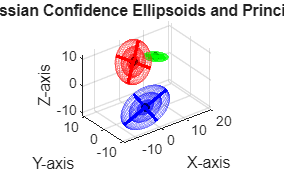


% Setup the figure
figure;
hold on;
grid on;
axis equal;
view(3); % View in 3D space
xlabel('X-axis'); ylabel('Y-axis'); zlabel('Z-axis');
title('3D Gaussian Confidence Ellipsoids and Principal Axes');

% Colors for each class
colors = {'r', 'g', 'b'};

% Plot for each class
plotClassEllipsoids(mu_a, covm_a, colors{1});
plotClassEllipsoids(mu_b, covm_b, colors{2});
plotClassEllipsoids(mu_c, covm_c, colors{3});

hold off;


function plotClassEllipsoids(mu, covm, color)
    % 1. Get eigenvalues (D) and eigenvectors (V)
    [V, D] = eig(covm);
    
    % The lengths of the semi-axes are the square roots of the eigenvalues
    % (which represent 1 standard deviation along the principal axes)
    radii_1std = sqrt(diag(D))';
    
    % Define the standard deviations we want to plot
    stdDevs = [1, 2, 3];
    
    % Loop through 1, 2, and 3 standard deviations
    for sd = stdDevs
        % Scale the base radii by the standard deviation level
        current_radii = radii_1std * sd;
        
        % Generate a standard axis-aligned ellipsoid at the origin
        % syntax: ellipsoid(xc, yc, zc, xr, yr, zr, n)
        [X, Y, Z] = ellipsoid(0, 0, 0, current_radii(1), current_radii(2), current_radii(3), 30);
        
        % Rotate and translate the ellipsoid points
        % Pack points into an N x 3 matrix
        pts = [X(:), Y(:), Z(:)];
        
        % Apply rotation (V) and shift to the mean (mu)
        rotated_pts = (pts * V') + mu;
        
        % Reshape back into surface grids for plotting
        X_rot = reshape(rotated_pts(:,1), size(X));
        Y_rot = reshape(rotated_pts(:,2), size(Y));
        Z_rot = reshape(rotated_pts(:,3), size(Z));
        
        % Plot the ellipsoid surface with transparency (Alpha)
        mesh(X_rot, Y_rot, Z_rot, 'FaceColor', 'none', 'EdgeColor', color, 'EdgeAlpha', 0.2);
    end
    
    % 2. Plot the Principal Axes (drawn out to 3 standard deviations)
    for d = 1:3
        % Direction vector of the principal axis
        axis_direction = V(:, d)'; 
        % Half-length of the axis at 3 standard deviations
        half_length = radii_1std(d) * 3; 
        
        % Calculate start and end points for the line
        p_start = mu - half_length * axis_direction;
        p_end = mu + half_length * axis_direction;
        
        % Draw the principal axis line using matlab's line() function
        line([p_start(1), p_end(1)], ...
             [p_start(2), p_end(2)], ...
             [p_start(3), p_end(3)], ...
             'Color', color, 'LineWidth', 2);
    end
    
    % Plot the center mean point
    plot3(mu(1), mu(2), mu(3), 'k.', 'MarkerSize', 15);
end

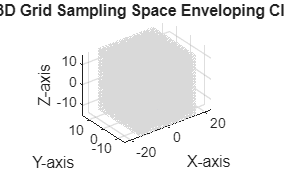

% question 7

Vaxis = [-15, 15];

Num = 40; % 40 points along X, 40 along Y, 40 along Z

grid_points = vol3D(Vaxis, Num);

% --- QUESTION 7: Generating and Visualizing the 3D Grid Space ---

% 1. Define bounds that wrap around all classes (-15 to 15 on all axes)
Vaxis = [-15, 15]; 
Num = 40; % Generates 40^3 = 64,000 regular grid points

% 2. Call your custom vol3D function
grid_points = vol3D(Vaxis, Num);

% 3. Overlay the grid onto your existing Question 6 figure
hold on;

% Plot the grid points as a light gray background cloud
% grid_points(:,1) is X, grid_points(:,2) is Y, grid_points(:,3) is Z
plot3(grid_points(:,1), grid_points(:,2), grid_points(:,3), ...
      '.', 'Color', [0.85 0.85 0.85], 'MarkerSize', 2);

% Push the grid points to the background visual layer so ellipsoids stay clear
grid on;
title('Question 7: 3D Grid Sampling Space Enveloping Class Ellipsoids');
hold off;